clear; clc;

# 1-1

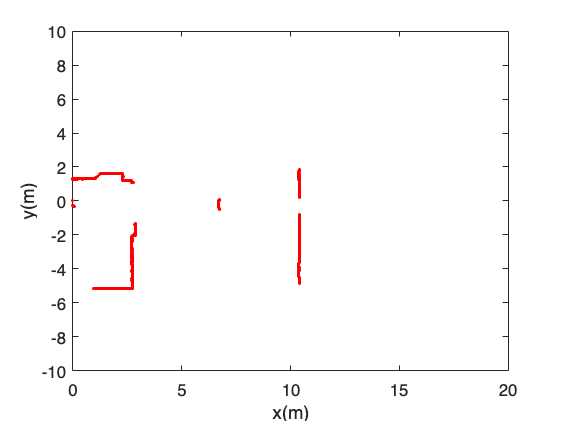

load('lidar_data.mat')

angle_start = -95;

angle_res1 = 0.1667;
angle_res23 = 0.5;

angle1 = angle_start : angle_res1 : angle_start + angle_res1 * 1140;
angle23 = angle_start : angle_res23 : angle_start + angle_res23 * 380;

x1 = cosd(angle1).*(lidar_data_1 / 1000); 
y1 = sind(angle1).*(lidar_data_1 / 1000);
z1 = zeros(1,length(x1));

x2 = cosd(angle23).*(lidar_data_2 / 1000); 
y2 = sind(angle23).*(lidar_data_2 / 1000); 
z2 = zeros(1,length(x2));

x3 = cosd(angle23).*(lidar_data_3 / 1000); 
y3 = sind(angle23).*(lidar_data_3 / 1000); 
z3 = zeros(1,length(x3));

figure(1); plot(x1,y1,'r.'); axis ([0 20 -10 10]); xlabel('x(m)'); ylabel('y(m)'); 

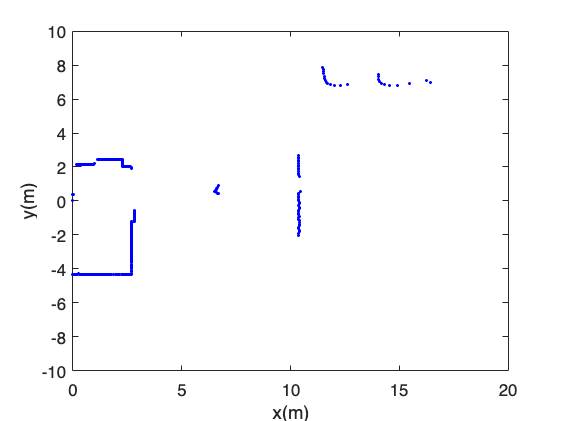

figure(2); plot(x2,y2,'b.'); axis ([0 20 -10 10]); xlabel('x(m)'); ylabel('y(m)'); 

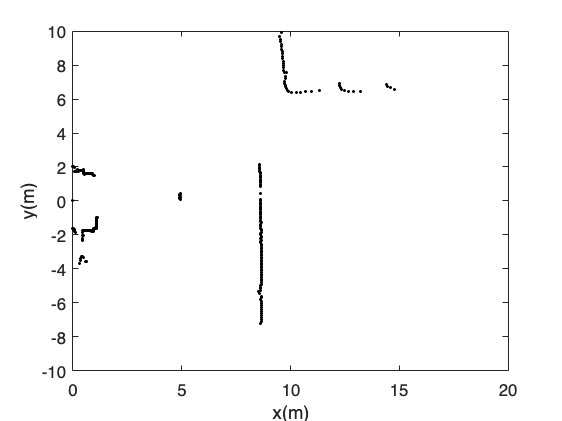

figure(3); plot(x3,y3,'k.'); axis ([0 20 -10 10]); xlabel('x(m)'); ylabel('y(m)');

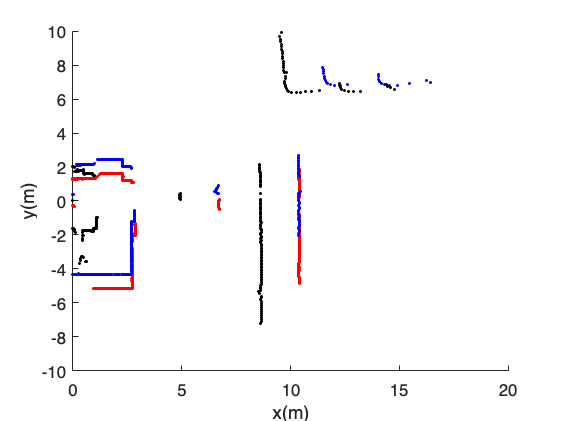


figure(4); hold on; axis ([0 20 -10 10]);
plot(x1,y1,'r.'); plot(x2,y2,'b.'); plot(x3,y3,'k.'); xlabel('x(m)'); ylabel('y(m)');


% 여기까지 동일함

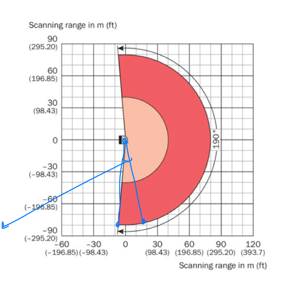

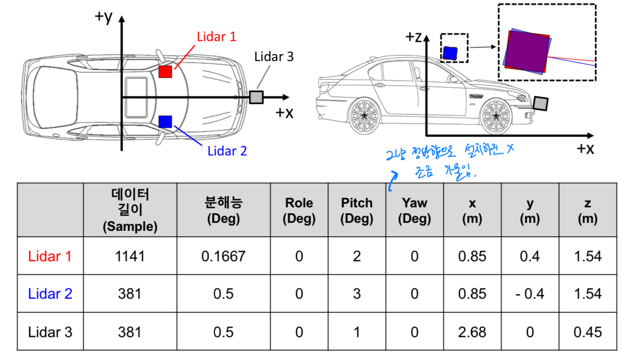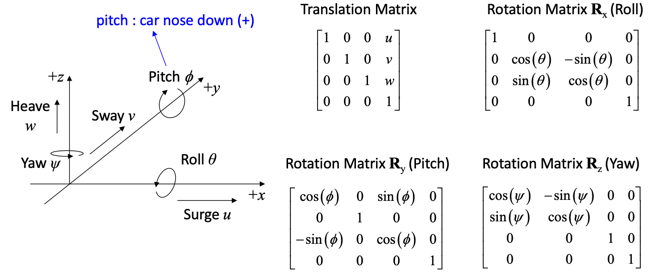

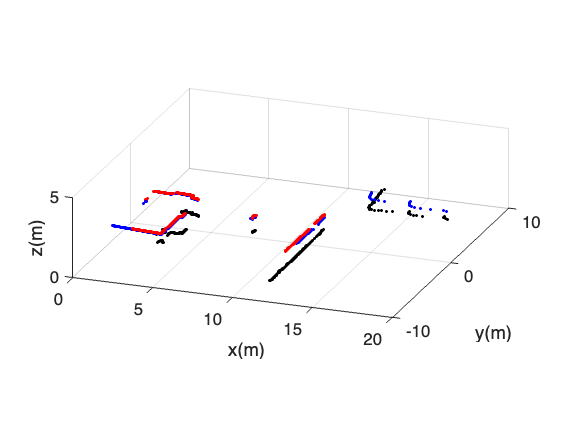

% 표에 나와있던 m단위의 Roll, Pitch, Yaw 기준으로 정렬

lidar1 = [x1; y1; zeros(1,length(x1)); ones(1,length(x1))]; 
lidar2 = [x2; y2; zeros(1,length(x2)); ones(1,length(x2))]; 
lidar3 = [x3; y3; zeros(1,length(x3)); ones(1,length(x3))];

% lidar roll, pitch, yaw (deg) --> Roll, Pitch, Yaw한 값을 다시 회전 변환 해줌으로써 정렬
lidar1_roll = 0; lidar1_pitch = 2; lidar1_yaw = 0; 
lidar2_roll = 0; lidar2_pitch = 3; lidar2_yaw = 0; 
lidar3_roll = 0; lidar3_pitch = 1; lidar3_yaw = 0;

% lidar x, y, z (m)   --> 평행이동한 값을 더해줌으로써 정렬
lidar1_x = 0.85; lidar1_y = 0.4; lidar1_z = 1.54; 
lidar2_x = 0.85; lidar2_y = -0.4; lidar2_z = 1.54; 
lidar3_x = 2.68; lidar3_y = 0; lidar3_z = 0.45;

R_pitch_1 = [cosd(lidar1_pitch) 0 sind(lidar1_pitch) 0; 
                                               0 1 0 0; 
            -sind(lidar1_pitch) 0 cosd(lidar1_pitch) 0;
                                               0 0 0 1]; 
L_1 = [1 0 0 lidar1_x;
       0 1 0 lidar1_y; 
       0 0 1 lidar1_z; 
       0 0 0 1];

lidar1 = R_pitch_1 * L_1 * lidar1;

R_pitch_2 = [cosd(lidar2_pitch) 0 sind(lidar2_pitch) 0; 
             0                  1                  0 0; 
            -sind(lidar2_pitch) 0 cosd(lidar2_pitch) 0;
             0                  0                  0 1]; 
L_2 = [1 0 0 lidar2_x;
       0 1 0 lidar2_y; 
       0 0 1 lidar2_z; 
       0 0 0 1];
lidar2 = R_pitch_2 * L_2 * lidar2;

R_pitch_3 = [cosd(lidar3_pitch) 0 sind(lidar3_pitch) 0; 
                                               0 1 0 0; 
            -sind(lidar3_pitch) 0 cosd(lidar3_pitch) 0;
                                               0 0 0 1]; 
L_3 = [1 0 0 lidar3_x;
       0 1 0 lidar3_y; 
       0 0 1 lidar3_z; 
              0 0 0 1];
lidar3 = R_pitch_3 * L_3 * lidar3;

figure(5); hold on; axis([0 20 -10 10 0 5]); 
view([20 20])
daspect([1 1 1]); grid on; 
plot3(lidar1(1,:), lidar1(2,:), lidar1(3,:), 'r.'); 
plot3(lidar2(1,:), lidar2(2,:), lidar2(3,:), 'b.'); 
plot3(lidar3(1,:), lidar3(2,:), lidar3(3,:), 'k.');
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');